load DOE_LHS2000

Ramp and Hold 

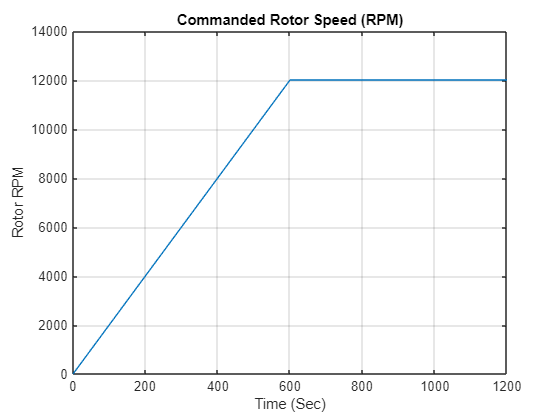

figure
plot(t,rpm)
xlabel('Time (Sec)')
ylabel('Rotor RPM')
ylim([0 14000])
grid on
title ('Commanded Rotor Speed (RPM)')

**Extract mean values of System outputs at steady state conditions** (t>=600sec)

simOutSSTable = array2table(zeros(height(simOut),width(simOut)-1));
simOutSSTable.Properties.VariableNames = simOut.Properties.VariableNames(2:end);
for i= 1:height(simOut)
    idx = simOut.HeatInput_kW{i,1}.Time>=seconds(600);
    simOutSSTable.HeatInput_kW(i)=mean(simOut.HeatInput_kW{i,1}.Heat_Input(idx));
    simOutSSTable.TurbineNozzleOpening(i)=mean(simOut.TurbineNozzleOpening{i,1}.NozzleOpening(idx));
    simOutSSTable.ShaftPower_kW(i)=mean(simOut.ShaftPower_kW{i,1}.Data(idx));
    simOutSSTable.ShaftMechEfficiency(i)=mean(simOut.ShaftMechEfficiency{i,1}.Data(idx));
    simOutSSTable.Thrust(i)=mean(simOut.Thrust{i,1}.Thrust_Core(idx));
    simOutSSTable.ThrustPT(i)=mean(simOut.ThrustPT{i,1}.Thrust_PT(idx));
    simOutSSTable.ThrustNet_N(i)=mean(simOut.ThrustNet_N{i,1}.Thrust_Net(idx));
end

**Steady State Results will be used for AI Modeling **

dataTable = horzcat(designVariables,simOutSSTable);
save dataTable_LHS2000 dataTable

regressionLearner

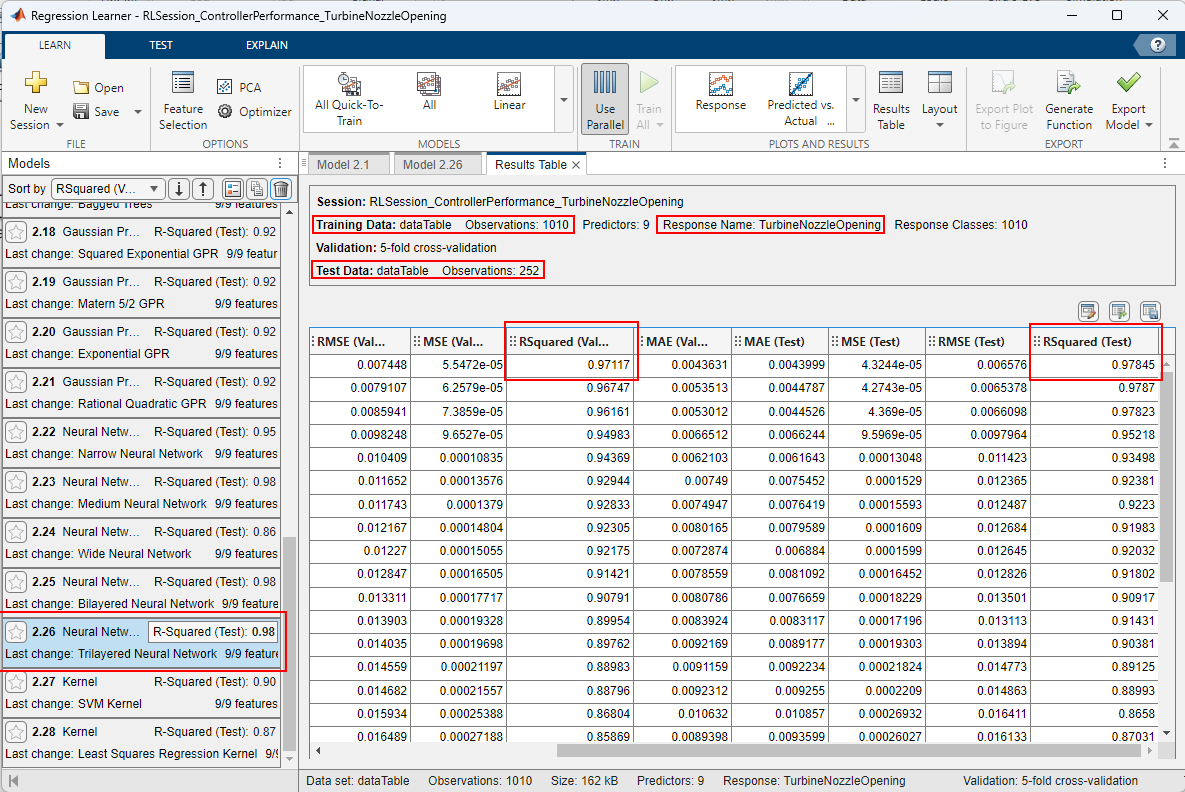

5 individual models were trained for predicting system reponses with the regressionLearner app. NN & GPR models performed best both for training and test data. 

load AI_Models

ResultsTable_ShaftPower = sortrows(ResultsTable_ShaftPower,"RSquared (Test)","descend");
ResultsTable_ThrustCore = sortrows(ResultsTable_ThrustCore,"RSquared (Test)","descend");
ResultsTable_ThrustPT = sortrows(ResultsTable_ThrustPT,"RSquared (Test)","descend");
ResultsTable_ControllerPerf_HeatInput = sortrows(ResultsTable_ControllerPerf_HeatInput,"RSquared (Test)","descend");
ResultsTable_ControllerPerf_TurbineNozzleOpening = sortrows(ResultsTable_ControllerPerf_TurbineNozzleOpening,"RSquared (Test)","descend");

Below are the observed accuracies:

Results_Summary = {[char(ResultsTable_ShaftPower.("Model Type")(1)) ' Test Set Accuracy for Shaft Power = ' num2str(ResultsTable_ShaftPower.("RSquared (Test)")(1)*100) '%'];...
                   [char(ResultsTable_ThrustCore.("Model Type")(1)) ' Test Set Accuracy for Core Thrust = ' num2str(ResultsTable_ThrustCore.("RSquared (Test)")(1)*100) '%'];...
                   [char(ResultsTable_ThrustPT.("Model Type")(1)) ' Test Set Accuracy for PT Thrust = ' num2str(ResultsTable_ThrustPT.("RSquared (Test)")(1)*100) '%'];...
                   [char(ResultsTable_ControllerPerf_HeatInput.("Model Type")(1)) ' Test Set Accuracy for Heat Input = ' num2str(ResultsTable_ControllerPerf_HeatInput.("RSquared (Test)")(1)*100) '%'];...
                   [char(ResultsTable_ControllerPerf_TurbineNozzleOpening.("Model Type")(1)) ' Test Set Accuracy for Nozzle Opening = ' num2str(ResultsTable_ControllerPerf_TurbineNozzleOpening.("RSquared (Test)")(1)*100) '%']};
disp(Results_Summary);

    {'Neural Network Test Set Accuracy for Shaft Power = 99.2986%'   }
    {'Neural Network Test Set Accuracy for Core Thrust = 98.9689%'   }
    {'Neural Network Test Set Accuracy for PT Thrust = 99.6329%'     }
    {'Neural Network Test Set Accuracy for Heat Input = 99.3151%'    }
    {'Neural Network Test Set Accuracy for Nozzle Opening = 97.8701%'}


save AI_Models NN_ShaftPower NN_ThrustCore NN_ThrustPT NN_HeatInput NN_TurbNozzleOpening ResultsTable_ShaftPower ResultsTable_ThrustCore ResultsTable_ThrustPT ...
    ResultsTable_ControllerPerf_HeatInput ResultsTable_ControllerPerf_TurbineNozzleOpening Results_Summary;